# Laboratorio 16 de Febrero del 2023, Análisis Aplicado, ITAM

## Técnica doblez

fun = 'rosenbrock';
x = [1.5 1.5]';
g = gradiente(fun,x);
B = hessiana(fun, x);

norm(g)

ans = 475.3001


v = eig(B)

v = 	1.0e+03 *

    0.0265
    2.2755



pN = -(B\g)

pN =    -0.0034
    0.7399


pC = -((g'*g)/(g'*B*g))*g

pC =    -0.1985
    0.0660


normaCa = norm(pC)

normaCa = 0.2092

normNew = norm(pN)

normNew = 0.7400

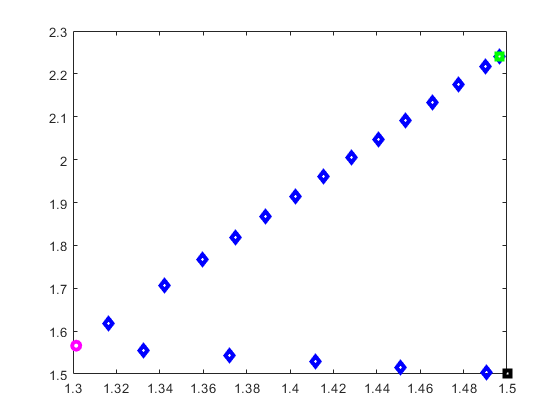

Delta = linspace(0.01, 0.8, 20)';

P = zeros(2,20);


for k = 1:20
    radio = Delta(k);
    ps = doblez(B,g,radio);
    P (:,k) = ps + x;
end


plot(P(1,:), P(2,:),'db',x(1),x(2),'sk','LineWidth',3)

hold on
w = pN + x;
z = pC + x;
plot(w(1),w(2),'sg',z(1), z(2),'om', 'LineWidth',3)



ps = doblez(B,g,0.01);
p  = [pN ps]

p =    -0.0034   -0.0095
    0.7399    0.0032


## Punto de Cauchy